

R = 6.3781366e6;
mu = 3.98597919e14; %(m^3/s^2)
MJD = 6.0618608e4;


% Topocentric-Horizon Coordinates (East-North-Up)
x = -6.1632886e6;
y = -2.6828774e6;
z = -3.8438538e6;

x1 = 2.2803628e3;
y1 = -6.9556447e3;
z1 = -1.9716421e3;

% Longitude
longitude = -81.070912 + 360 ;  

% Latitude
latitude     = -5.9356847;  

% MJD verisine göre vernal ekinoksun boylamı
UT = 14 + 35/60 + 31.2/60/60;
%UT =  4.80000018607825; 
JD = 2400000.5 + MJD;

J0 = JD - UT/24 ;

T0 = (J0 -2451545)/36525;

Theta_g0m = 100.4606184 + 36000.77004*T0 + 0.000387933*T0^2 - 2.583*10^(-8)*T0^3;

Theta_g0 = Theta_g0m - fix(Theta_g0m/360)*360;

Theta_g = Theta_g0 + 360.98564724/24*UT ;

Theta_real = Theta_g + longitude -360 ;

% Topocentric horizon to geocentric equatorial(ECEF)
QxX1 = [-sind(longitude) -sind(latitude)*cosd(longitude) cosd(latitude)*cosd(longitude) ]; 
QxX2 = [ cosd(longitude) -sind(latitude)*sind(longitude) cosd(latitude)*sind(longitude) ];
QxX3 = [ 0                cosd(latitude)                 sind(latitude)                 ];

% Topocentric Horizon konum vektörü
q = [x; y; z];

% Topocentric Horizon hız vektörü
qv = [x1; y1; z1];

% ECEF konum vektörü
Rxx = dot(QxX1,q);
Rxy = dot(QxX2,q);
Rxz = dot(QxX3,q);
RxX = [Rxx Rxy Rxz];

% ECEF hız vektörü
Vxx = (QxX1 * qv);
Vxy = (QxX2 * qv);
Vxz = (QxX3 * qv);
VxX = [Vxx Vxy Vxz];

% Ground station konum vektörü
GSi_real = R.*[cosd(longitude)*cosd(latitude) cosd(latitude)*sind(longitude) sind(latitude)];

% ECEF konum vektörü
ecef_r = RxX + GSi_real;

% ECEF to ECIF matirisi
ecif_mxi = [cosd(Theta_g)  sind(Theta_g) 0];
ecif_myi = [-sind(Theta_g) cosd(Theta_g) 0];
ecif_mzi = [0               0            1];

% ECIF konum vektörü 
ecif_rxi = dot(ecif_mxi,ecef_r);
ecif_ryi = dot(ecif_myi,ecef_r);
ecif_rzi = dot(ecif_mzi,ecef_r);

ecif_r = [ecif_rxi ecif_ryi ecif_rzi];

% ECIF hız vektörü
vx = dot(ecif_mxi,VxX);
vy = dot(ecif_myi,VxX);
vz = dot(ecif_mzi,VxX);

v = [vx vy vz];

% r büyüklüğü
rm = sqrt (dot(ecif_r,ecif_r));

% hız büyüklüğü
vm = sqrt (dot(v,v));

% radyal hız
vr = dot (v,ecif_r/rm);

% açısal momentum vektörü
h = cross(ecif_r,v);

% açısal momentum büyüklüğü
hm = sqrt (dot(h,h));

% inclination derece
i = acosd (h(3)/hm);

% unit z
K = [0 0 1];
 
% node line vektörü
N = cross(K,h);

% node line büyüklüğü
Nm = norm(N);
% right escending node derece
raan = acosd (N(1)/Nm);  % N(2) < 0 ise 360tan çıkar
 if N(2) < 0
     raan = 360 -raan;
 end 
% eccentricity vektörü
e = 1/mu * (cross(v,h) - mu * ecif_r/rm);

% eccentricity büyüklüğü
em = sqrt (dot(e,e));

% perigeelerin tartışması derece
argumentOf_p = acosd (dot(N,e)/(Nm*em));  %e(3) < 0 ise  360 tan çıkar
 if e(3) < 0
     argumentOf_p = 360 - argumentOf_p;
 end
% true anomaly
trueAnomaly = acos(dot(e/em , ecif_r/rm)); % Vr < 0 ise 360 tan çıkar
 if vr < 0
     trueAnomaly = 2*pi-trueAnomaly;
 end
% ECIF to Perifocal 
QXx = [cosd(raan)*cosd(argumentOf_p)-sind(raan)*sind(argumentOf_p)*cosd(i)  sind(raan)*cosd(argumentOf_p)+cosd(raan)*cosd(i)*sind(argumentOf_p) sind(i)*sind(argumentOf_p) ;
      -cosd(raan)*sind(argumentOf_p)-sind(raan)*cosd(i)*cosd(argumentOf_p) -sind(raan)*sind(argumentOf_p)+cosd(raan)*cosd(i)*cosd(argumentOf_p) sind(i)*cosd(argumentOf_p) ;
       sind(raan)*sind(i)                            -cosd(raan)*sind(i)                            cosd(i)         ];

% Perifocal frame konum vektörü
Perifocal_r = QXx * ecif_r.' ;

% Perifocal frame hız vektörü
Perifocal_v = QXx * v.'      ;

% Semimajor axis, perigee ve apogee uzaklıkları
a = (hm^2/mu)*(1/(1-em^2));
r_a = a * (1+em);
r_p = 2 * a - r_a ;

% Periyot
T = 2*pi*sqrt(a^3/mu);

% başlangıç zamanının hesaplanması
E_real = 2 * atan(sqrt((1-em)/(1+em)) * tan(trueAnomaly/2));
M_real = mod(E_real - em * sin(E_real),2*pi);
t = M_real * T / (2*pi);


% V escape ve delta V
v_p = sqrt(mu*(2/r_p-1/a));
Vesc = sqrt (2*mu/r_p);
delV_min = Vesc - v_p;

% Gerçek Anomali (0 ile 360 derece arasında)
theta_real_orbit = linspace(0, 2*pi, 100000); % Rad cinsinden

% Yörünge Denkleminden Radial Mesafe
r_rael = a * (1 - em^2) ./ (1 + em*cos(theta_real_orbit));

% Yörünge düzleminde x, y koordinatları
x_orbit_real = r_rael .* cos(theta_real_orbit);
y_orbit_real = r_rael .* sin(theta_real_orbit);
z_orbit_real = zeros(size(x_orbit_real)); % İlk etapta 2D

% Rotasyon Matrisi ile yörüngenin 3D'ye dönüşümü
rotMatrix_real = rotz(raan) * rotx(i) * rotz(argumentOf_p); % RAAN, Inclination ve ArgPerigee dönüşümleri
orbit3D_real = rotMatrix_real * [x_orbit_real; y_orbit_real; z_orbit_real];

% Dünya'nın Çapı ve Yüzeyi
earth_radius = R;% Dünya yarıçapı (m)
[X, Y, Z] = sphere(100); % Küre oluştur

% Siyah Nokta Koordinatları
ground_station = [9.846553405651499e+05; -6.267059896937207e+06; -6.595760735180455e+05];
debris_given_time = [ecif_rxi ecif_ryi ecif_rzi];




theta = trueAnomaly; % İlk true anomaly

dtheta = 0.0000006;
% Maksimum tahmini eleman sayısı
max_elements = ceil((6*pi) / dtheta);

% Ön tahsis edilmiş matrisler
intersection_points = NaN(max_elements, 3); % Kesin boyut için 3 sütun
intersection_times = NaN(max_elements, 1); % Zamanlar için

% Bulunan kesişim sayısını takip etmek için sayaç
num_intersections = 0;
dt = 0 ;
while theta < 6*pi+trueAnomaly % Bir tam yörünge turu hesaplama
    
    % Kepler Denklemi için Eccentric Anomaly Hesaplama
    E_start = 2 * atan(sqrt((1-em)/(1+em)) * tan(theta/2));
    if E_start < 0
        E_start = E_start +2*pi;
    end
    E_end = 2 * atan(sqrt((1-em)/(1+em)) * tan((theta+dtheta)/2));
    if E_start < 0
        E_end = E_end +2*pi;
    end
    E_start = mod(E_start, 2*pi); % Eccentric Anomaly için
    E_end = mod(E_end, 2*pi);     % Eccentric Anomaly için

    % Ortalama Anomaly
    M_start = mod(E_start - em * sin(E_start),2*pi);
    M_end = mod(E_end - em * sin(E_end),2*pi);

    %M_start = mod(M_start, 2*pi); % Mean Anomaly için
    %M_end = mod(M_end, 2*pi);

    % Zaman Hesaplama
    t_start = M_start * T / (2*pi);
    t_end = M_end * T / (2*pi);

    % Zaman Farkı
    time_difference2 = t_end - t_start;

    if time_difference2 < 0
        time_difference2 = 0.0009;
    end
    % Kutupsal mesafe hesaplama
    r = a * (1 - em^2) ./ (1 + em * cos(theta)); % Kutupsal mesafe
    x_orbit = r * cos(theta);
    y_orbit = r * sin(theta);
    z_orbit = 0; 

    % 3D dönüşüm uygulayın
    rotMatrix = rotz(raan) * rotx(i) * rotz(argumentOf_p);
    orbit_point = rotMatrix * [x_orbit; y_orbit; z_orbit];

    % Zaman güncellemesi
    dt = dt + time_difference2;

    % Longitude güncellemesi
    longitude2 = mod(longitude + 360.98564724 / 24 * ((dt) / 3600),360);
    GSi2 = R .* [cosd(longitude2) * cosd(latitude), cosd(latitude) * sind(longitude2), sind(latitude)];
    ecif_GSi2 = GSi2 / norm(GSi2);

    % Düzlem parametreleri
    A = ecif_GSi2(1); 
    B = ecif_GSi2(2); 
    C = ecif_GSi2(3); 
    D = -dot(ecif_GSi2, GSi2);

    % Düzlem denklemini kontrol et
    plane_equation_residual = abs(A * orbit_point(1) + B * orbit_point(2) + C * orbit_point(3) + D);
    if plane_equation_residual < 1 % Daha hassas tolerans
        % Kesişim noktasını ve zamanı kaydet
        num_intersections = num_intersections + 1;
        intersection_points(num_intersections, :) = orbit_point'; % Noktayı kaydet
        intersection_times(num_intersections) = dt; % Zamanı kaydet

        if num_intersections >=4
            % Kesişim zamanlarını sırala
            sorted_times = sort(intersection_times(1:num_intersections));

            % En büyük iki zamanı al
            max1 = sorted_times(1);       % En büyük
            max2 = sorted_times(2);     % İkinci en büyük
    
            % En küçük iki zamanı al
            min1 = sorted_times(3);         % En küçük
            min2 = sorted_times(4);         % İkinci en küçük

            % Farkların mutlak değerlerini hesapla ve topla
            total_diff = abs(max1 - max2) + abs(min1 - min2);

            % Toplam farkı görüntüle
            disp(['Toplam zaman farkı: ', num2str(total_diff)]);
        end
    end

    % True anomaly güncellemesi
    theta = theta + dtheta;
end

Toplam zaman farkı: 1571.3969



% Kullanılan kısmı kes
intersection_points = intersection_points(1:num_intersections, :);
intersection_times = intersection_times(1:num_intersections);

% Tüm kesişim noktalarını yazdır
if isempty(intersection_points)
    disp('Kesişim bulunamadı.');
else
    disp('Kesişim Noktaları ve Zamanları:');
    for k = 1:num_intersections
        disp(['Kesişim Noktası: ', num2str(intersection_points(k, :)), ...
              ', Zaman: ', num2str(intersection_times(k)), ' s']);
    end
end

Kesişim Noktaları ve Zamanları:


Kesişim Noktası: 4903942.5632     -4787134.9995      2500297.8457, Zaman: 5642.9481 s
Kesişim Noktası: 3291584.048     -5033116.7055     -3920090.7559, Zaman: 6553.0032 s
Kesişim Noktası: 4905883.9793     -4798813.0671      2471194.4317, Zaman: 12046.6117 s
Kesişim Noktası: 4102451.6264     -5434904.6113     -2307704.7341, Zaman: 12707.9535 s


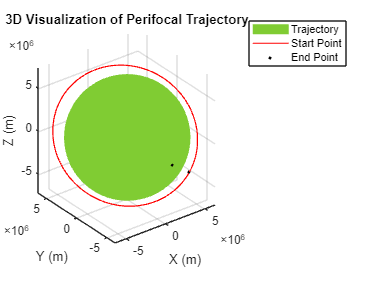


% Çizim
figure;

% Dünya küresini çiz
surf(X * earth_radius, Y * earth_radius, Z * earth_radius, ...
    'FaceColor', '[0.5, 0.8, 0.2]', 'EdgeColor', 'none'); % Dünya yüzeyi
hold on;

% Yörüngeyi Çiz
plot3(orbit3D_real(1,:), orbit3D_real(2,:), orbit3D_real(3,:), 'r-', 'LineWidth', 1);

% Siyah Noktaları Çiz
plot3(ground_station(1), ground_station(2), ground_station(3), 'ko', 'MarkerSize', 2, 'MarkerFaceColor', 'black'); % 1. Siyah nokta
plot3(debris_given_time(1), debris_given_time(2), debris_given_time(3), 'ko', 'MarkerSize', 2, 'MarkerFaceColor', 'black'); % 2. Siyah nokta
% Görsel Ayarlar
axis equal;

% Eksen limitlerini ayarla
axis([-2*r_a 2*r_a -2*r_a 2*r_a -2*r_a 2*r_a]);

% Eksen Etiketleri ve Başlık
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('3D Earth, Orbit, and Two Black Points with Extended Connecting Line');


% Görsel Ayarlar
xlabel('X Ekseni'); ylabel('Y Ekseni'); zlabel('Z Ekseni');
title('Düzlem Çizimi: A*x + B*y + C*z + D = 0');
grid on;

dt_range = linspace(0,2*pi,10000); % Zaman aralığı (radyan cinsinden)

% Perifocal konumlarının bileşenlerini saklamak için diziler
x_vals = zeros(1, length(dt_range));
y_vals = zeros(1, length(dt_range));
z_vals = zeros(1, length(dt_range));


% 3D Görslleştirme
hold on;

% Başlangıç ve Bitiş Noktaları
plot3(x_vals(1), y_vals(1), z_vals(1), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'green'); % Başlangıç noktası
plot3(x_vals(end), y_vals(end), z_vals(end), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'red'); % Bitiş noktası

% Grafik Ayarları
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('3D Visualization of Perifocal Trajectory');
grid on;
axis equal;
legend('Trajectory', 'Start Point', 'End Point');